% 参数设置
Lx = 1; Ly = 1; % 计算区域边长
M = 0;
D = 0;
alpha = 0;

N = 64; K = 30; 
global K1; K1 = 171;
w = 0.01;R = 0.; 
R1 = 0; 


Diagnostic information:
Fitness function: @(x)(1-w)*max_Sk(x,N,Lx,Ly,K)+w*energy(x)
Nonlinear constraint function: @(x)constraints(x,N,R,Lx,Ly,other_points,R1)
128 Variable(s)
2016 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
PopulationSize:    200
Generations:       50
TolFun:            0 
TolCon:            1e-06
InitialPopulation: 1-by-128
Display:           'diagnose'
PlotFcns:          @gaplotdistance
OutputFcns:        @GAoutputfcn
UseParallel:       1 
End of diagnostic information.

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          10790       48.5067    1.435e-13      0
    2          20500       48.3584    2.771e-07      0
    3          30210       48.1541    2.771e-07      0
    4          39920       47.8833    2.771e-07      0
   

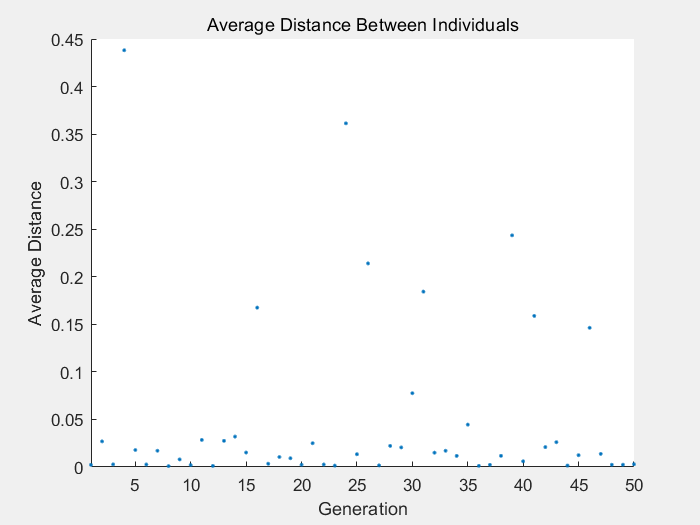

% start_points = all_points{2};
% % start_points = [Lx, Ly] .* rand(N,2);
% other_points = all_points{1};
% all_points{2} = optimize_points(start_points, N, Lx, Ly, K, R, w, other_points, R1);

objective = 包含以下值的 function_handle :
    @(x)1*total_potential_energy(x,N,Lx,Ly,K,D,alpha)


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     129    2.435255e+05    1.003e-01    5.439e+05
    1     258    2.373533e+05    1.003e-01    5.201e+05    7.007e-03
    2     387    1.920591e+05    1.003e-01    4.264e+05    5.420e-02
    3     516    1.452942e+05    1.004e-01    3.295e+05    1.433e-01
    4     645    1.428363e+05    1.004e-01    3.173e+05    4.603e-03
    5     774    1.425686e+05    1.004e-01    3.122e+05    5.118e-04
    6     903    9.852616e+04    1.006e-01    3.964e+05    2.535e-01
    7    1032    8.522838e+04    1.004e-01    3.672e+05    4.364e-02
    8    1161    8.123405e+04    1.003e-01    3.536e+05    1.077e-02
    9    1290    7.636369e+04    1.002e-01    3.561e+05    1.517e-02
   10    1419    5.841233e+04    9.964e-02    2.977e+05    9.879e-02
   11    1548    5.585522e+04    9.966e-02    3.160e+05    3.601e-02
   12    1677    4.667609e+04    9.987e-02    3

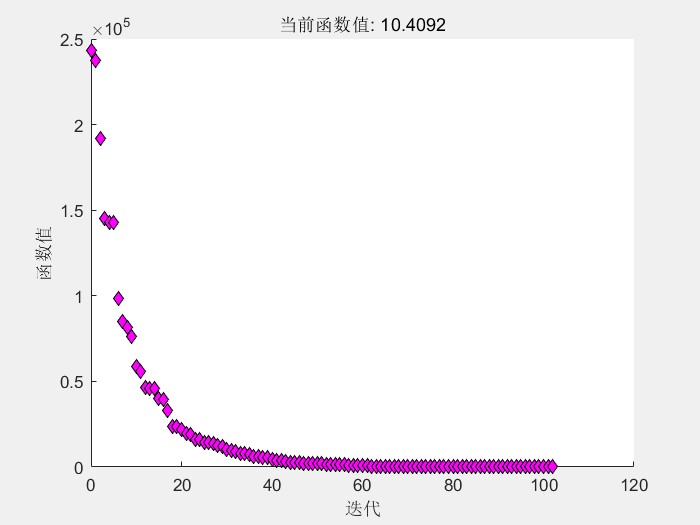


fmincon stopped by the output or plot function.



% start_points = all_points{2};
start_points = [Lx, Ly] .* rand(N,2);
all_points{2} = generate_hyperuniform_points(start_points, N, Lx, Ly, K, R, D, alpha);

% all_points{2} = optimize_points(start_points, N, Lx, Ly, K, R, w, other_points, R1);

% hyperuniform_points = cut_circle(hyperuniform_points, N, Lx, Ly);
% hyperuniform_points = hyperuniform_points(all(~isnan(hyperuniform_points), 2), :);

hyperuniform_points = all_points{2};
N = 64;
min_distance = Inf;
for i = 1:size(hyperuniform_points, 1)
    for j = i+1:size(hyperuniform_points, 1)
        % 计算两点之间的欧几里得距离
        distance = norm(hyperuniform_points(i, :) - hyperuniform_points(j, :));
        
        % 更新最小距离
        if distance < min_distance
            min_distance = distance;
        end
    end
end
min_distance

min_distance = 0.1254

max_Sk(hyperuniform_points, N, Lx, Ly, K)

ans = 15.8104

10*log10(max_Sk(hyperuniform_points, N, Lx, Ly, K)/N)

ans = -6.0724

total_potential_energy(hyperuniform_points, N, Lx, Ly, K, D, alpha) 

ans = 10.4092

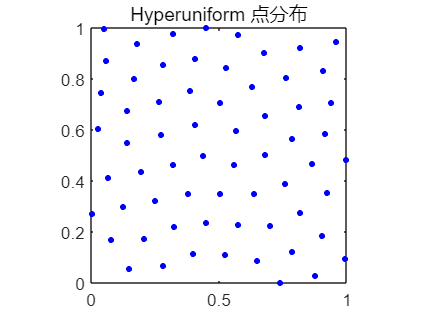

% 绘制点分布
figure ;
hold on;
scatter(hyperuniform_points(:, 1), hyperuniform_points(:, 2), 100, 'blue','.');
% scatter(all_points{1}(:, 1), all_points{1}(:, 2), 2000, 'blue','.');
% scatter(all_points{2}(:, 1), all_points{2}(:, 2), 1000, 'red','.');
axis equal;  
xlim([0, Lx]);
ylim([0, Ly]);
title('Hyperuniform 点分布'); 
box on;
hold off;

% 绘制圆
% hold on;
% theta = 0:0.01:2*pi;
% x_circle = Lx/2 * cos(theta) + Lx/2;
% y_circle = Lx/2 * sin(theta) + Lx/2;
% plot(x_circle, y_circle, 'LineWidth', 1);
% hold off;


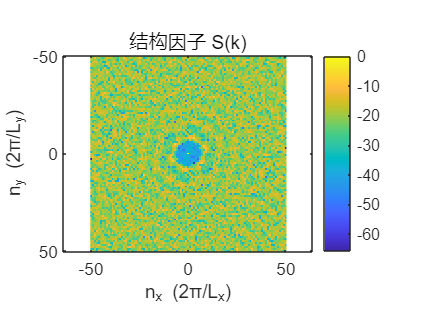


% 定义倒空间波矢范围
k_max = 50;         % 最大波矢值（单位：2π/L）
k_resolution = 101; % 分辨率
[kx, ky] = meshgrid(linspace(-k_max, k_max, k_resolution), ...
                    linspace(-k_max, k_max, k_resolution));

% 计算结构因子 S(k)
S = zeros(size(kx));
Mk = 0;
for i = 1:numel(kx)
    k = 2 * pi * [kx(i)/Lx, ky(i)/Ly];  % 波矢定义（实际物理单位）
    if kx(i) ^2 + ky(i) ^2 <= K
        Mk = Mk+1;
    end
    sum_exp = 0;
    for j = 1:N
        sum_exp = sum_exp + exp(1j * dot(k, hyperuniform_points(j, :)));
    end
    S(i) = abs(sum_exp)^2 / N;
end

Mk = (Mk-1)/2;
chi = Mk /2 /N;
norm_S = 10 * log10(S / max(S(:)));
% 绘制结构因子
figure (2);
imagesc(kx(1,:), ky(:,1), norm_S); % 对数刻度，避免 log(0)
axis equal;
xlabel('n_x (2π/L_x)');
ylabel('n_y (2π/L_y)');
title('结构因子 S(k)');
colorbar;

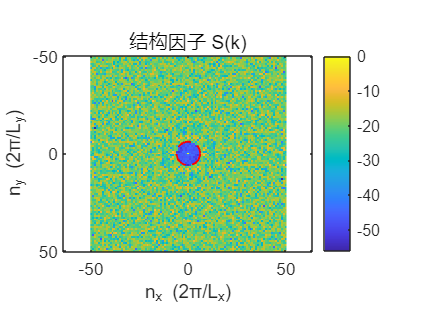

% 叠加截止区域圆（K）
hold on;
theta = 0:0.01:2*pi;
x_circle = sqrt(K) * cos(theta);
y_circle = sqrt(K) * sin(theta);
plot(x_circle, y_circle, 'r--', 'LineWidth', 1);
hold off;

% 计算波矢模长 |k|
K_ = 2*pi/Lx * sqrt(K)  

K_ = 38.2191

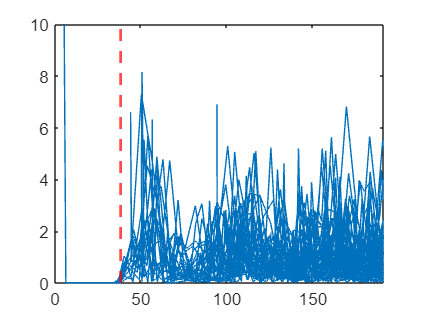

norm_k = 2 * pi / Lx * sqrt(kx.^2 + ky.^2);  % 注意！单位：2π/L
norm_k_flat = norm_k(:);        % 展平为一维数组
S_flat = S(:);                  % 展平为一维数组

% 定义模长平均的范围
bin_edges = linspace(0, max(norm_k_flat), 50);  % 100 个 bins
bin_centers = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

% 将 S(k) 按 |k| 分组并计算平均值
S_mean = zeros(1, length(bin_centers));
for i = 1:length(bin_edges)-1
    mask = (norm_k_flat >= bin_edges(i)) & (norm_k_flat < bin_edges(i+1));
    S_mean(i) = mean(S_flat(mask));
end

% 绘制 S(k) 随 |k| 的变化曲线
figure;
plot(norm_k_flat, S_flat); 
xline(K_, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Cutoff K');
xlim([0, 5*K_]);
ylim([0, 10]);

function points = optimize_points(hyperuniform_points, N, Lx, Ly, K, R, w, other_points, R1)

    energy = @(x) total_potential_energy(x, N, Lx, Ly, K, 0, 0);
    objective =  @(x) (1-w) * max_Sk(x, N, Lx, Ly, K) + w * energy(x);
    % 定义约束条件
    nonlcon = @(x) constraints(x, N, R, Lx, Ly, other_points, R1);
    points = reshape(hyperuniform_points, 1, []);

    % 示例：使用遗传算法
    options_ga = optimoptions('ga', ...
        'InitialPopulationMatrix',points,...
        'PopulationSize', 200, ...
        'MaxGenerations', 50 , ...
        'FunctionTolerance', 0,...
        'ConstraintTolerance',1e-6,...
        'OutputFcn',@GAoutputfcn,...
        'Display','diagnose', 'UseParallel', true, 'PlotFcn','gaplotdistance');
    optimized_points = ga(objective, 2*N, [], [], [], [], zeros(2*N, 1), ones(2*N, 1), nonlcon, options_ga);
    points = reshape(optimized_points, N, 2);
end

function max_Sk = max_Sk(points, N, Lx, Ly, K)
    global K1;
    points = reshape(points, N, 2);
    max_Sk = 0;
    
    for nx = -50:50
        for ny = -50:50
            if nx ^2 + ny^2 <= K1 & nx ^2 + ny^2 ~= 0
                k = 2 * pi * [nx/Lx, ny/Ly]; 
                Ck = 0;
                for j = 1:N-1
                    for l = j+1:N
                        Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
                    end
                end
                if 1+2*Ck/N > max_Sk
                    max_Sk = 1+2*Ck/N;
                    max_k = [nx,ny];
                end
            end
        end
    end
%     assignin('base', 'max_k', max_k);
end


function hyperuniform_points = generate_hyperuniform_points(start_points, N, Lx, Ly, K, R, D, alpha)
    % 生成 Hyperuniform 点分布
    % 输入参数：
    %   N: 点的数量
    %   Lx, Ly: 计算区域的边长
    %   K: 倒空间截止波数
    %   R: 点的最小间距（硬球半径）
    % 输出：
    %   hyperuniform_points: N x 2 矩阵，表示点的坐标

    % 初始化随机点分布
    points = start_points;
    
    % 定义优化目标函数
    objective =  @(x) 1 * total_potential_energy(x, N, Lx, Ly, K, D, alpha)

    % 定义约束条件
    nonlcon = @(x) constraints(x, N, R, Lx, Ly, [], 0);

    % 示例：使用遗传算法
%     options_ga = optimoptions('ga', 'PopulationSize', 100, 'MaxGenerations', 100, 'Display','iter', 'UseParallel', true);
%     optimized_points = ga(objective, 2*N, [], [], [], [], zeros(2*N, 1), ones(2*N, 1), nonlcon, options_ga);

%     优化选项
    options = optimoptions('fmincon', 'Algorithm', 'interior-point', ...
                           'Display', 'iter', 'MaxIterations', 200, ...
                           'ConstraintTolerance',1e-10,...
                           'FunctionTolerance',1,...
                           'MaxFunctionEvaluations', 500 * N, ...
                           'PlotFcn','optimplotfval', ...
                           'OutputFcn',@myOutputFcn);

%     调用 fmincon 进行优化
    optimized_points = fmincon(objective, points, [], [], [], [], ...
                               zeros(N, 2), [Lx, Ly] .* ones(N, 2), ...
                               nonlcon, options);

    % 返回优化后的点分布
    hyperuniform_points = optimized_points;
end

function phi = total_potential_energy(points, N, Lx, Ly, K, D, alpha) 
    % 计算总势能
    global K1;
    phi = 0;
    M = 0;
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    
    % 遍历所有波矢 k
    for nx = -50:50
        for ny = -50:50
            if nx ^2 + ny^2 <= K && nx ^2 + ny^2 ~= 0 % k在K内，相当于辅助函数
                k = 2 * pi * [nx / Lx, ny / Ly]; % 波矢
                C0 = -N/2 + D * norm(k) ^ alpha;
                Ck = 0;
                for j = 1:N-1
                    for l = j+1:N
                        Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
                    end
                end
                phi = phi + (C0 - Ck) ^2;
            end

%             if nx ^2 + ny^2 <= K1 && nx ^2 + ny^2 >= K
%                 k = 2 * pi * [nx/Lx, ny/Ly]; 
%                 for j = 1:N-1
%                     for l = j+1:N
%                         Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
%                     end
%                 end
%                 phi = phi + Ck;
%             end
        end
    end
end

function [c, ceq] = constraints(points, N, R, Lx, Ly, other_points, R1)
    % 定义约束条件
    N1 = size(other_points, 1);
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    c = []; % 不等式约束
    ceq = []; % 等式约束

    % 最小间距约束
    for j = 1:N-1
        for l = j+1:N
            dist = norm(points(j, :) - points(l, :));
            c = [c; R - dist]; % 确保 dist >= R
        end
    end
    
    if ~isempty(other_points)
        for j = 1:N
            for i = 1:N1
                dist = norm(points(j, :) - other_points(i, :));
                c = [c; R1 - dist];
            end
        end
    end
end

function points = cut_circle(points, N, Lx, Ly)
    for n = 1:N
        if norm(points(n, :) - [Lx/2, Ly/2]) >= Lx/2
            points(n, :) = [NaN, NaN];
        end
    end
end    

function stop = myOutputFcn(~, optimValues, state)
    persistent targetValue
    if isempty(targetValue)
        targetValue = 0; % 设定目标函数值的阈值
    end
    
    stop = false;
    
    switch state
        case 'iter'
            % 在每次迭代时检查目标函数值
            if optimValues.fval <= targetValue
                disp(['目标函数值已达到: ', num2str(optimValues.fval)]);
                stop = true; % 终止优化
            end
    end
end

function [state,options,optchanged] = GAoutputfcn(options,state,flag)
    persistent overall_best_fval;
    persistent overall_best_x;
    
    if isempty(overall_best_fval) || strcmp(flag, 'init')
        overall_best_fval = Inf;
        overall_best_x = [];
    end
    
    if ~isempty(state.Score)
        [current_min, idx] = min(state.Score);
        
        % Only update if better than what we've seen before
        if current_min < overall_best_fval
            overall_best_fval = current_min;
            overall_best_x = state.Population(idx,:);
            assignin('base','bestXs',overall_best_x);
            assignin('base',"bestFvals",overall_best_fval);
        end
        
        % Display accurate information
%         fprintf('Generation %d: Current best = %f, Overall best = %f\n', ...
%                 state.Generation, current_min, overall_best_fval);
    end
    
    % Continue optimization
    optchanged = false;
end



